addpath('Classes')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',false);
sympref('TypesetOutput',true);

# U-Joint Kinematics Class Developement Script

This script aids in the developement and documentation of the UJ_Kin class. The class will generate position, velocity, and acceleration vectors of points belonging to various reference frames. 

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

if (~exist('UJ_Kin', 'var')) 

    UJ_Kin = UJ_Kin(VDefs); %Create an object of the class UJ_Kin

end 

To derive the equations of motion of the ball and plate system, we must first find the velocity and acceleration vectors for arbitrary displacements within the plate's frame of reference. We will describe a majority of our system with respect to the plate frame because we are interested in the $x $ and $y$ location of the ball relative to the plate. It is easy to define these displacements in a plane and complicated to attempt to describe the displacemnt of the ball in three dimensional space without using the methods presented here. In addition to the ease of describing the ball's displacement in the plate frame, the plate's inertia tensor


$$I_p^{(2)} = \left\lbrack \begin{array}{ccc}
I_p^{\textrm{xx}}  & 0 & 0\\
0 & I_p^{\textrm{yy}}  & 0\\
0 & 0 & I_p^{\textrm{zz}} 
\end{array}\right\rbrack$$


is diagonal in its own frame. Choosing S2 to describe many of its kinetic quantities is advantageous. 

A schematic of the system is shown in figure 2:

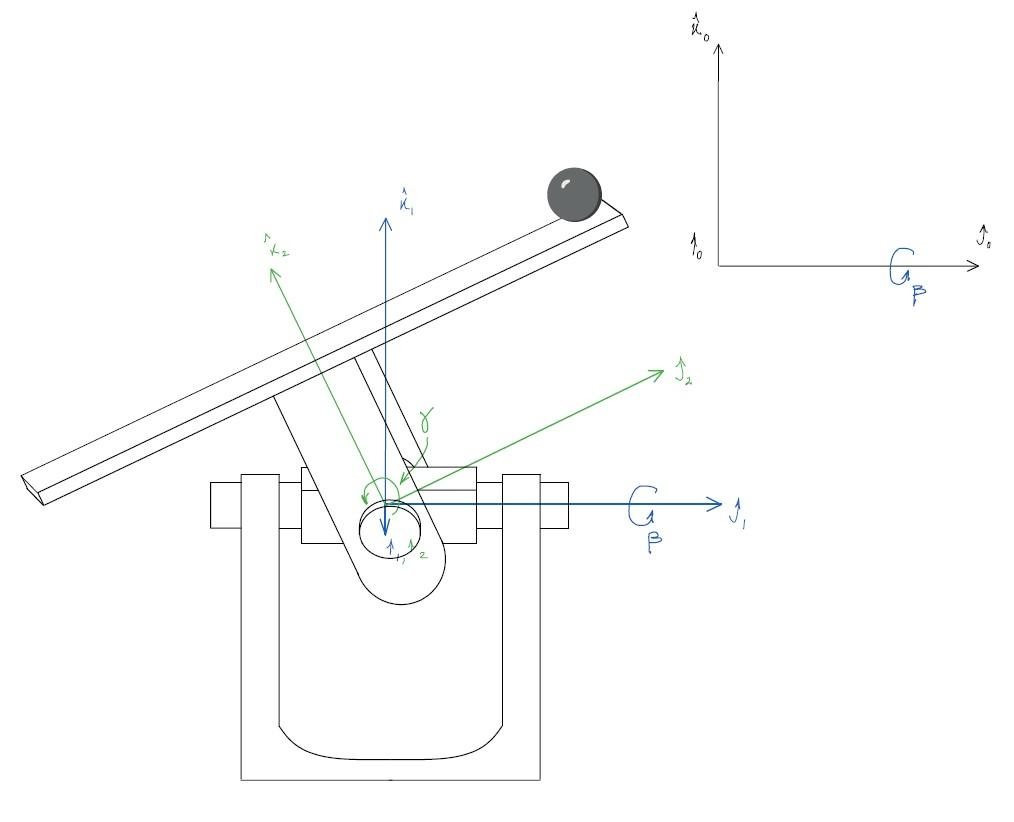

Figure 2: Schematic of the ball and plate system showing the choice of coordinate systems and associated rotation angles. 

The global frame will be denoted S0, the u-joint frame will be denoted S1, and the plate frame will be denoted S2. Frame S0 is the inertial frame of reference - differentiation of kinematic and kinetic quantities will occur with vectors expressed in this frame. In this way, results will be compatible with Newton's laws of motion. The S1 frame is attached to the u-joint block, it is fixed with respect to the joint's axles of rotation. S1 rotates about a shared y axis with S0 through angle $\beta$. Frame S2 rotates about a shared x axis with frame S1 through angle $\gamma$. The rotation matrices associated with these, $R^{01}, R^{10}, R^{12}, and~ R^{21}$ are defined in appendix 1. 

## Notes on Notation for the Kinematic Analysis

- Lower indices follow Einstein summation convention where no distinction is made between the covariant and contravariant parts of a tensor (all rotations are proper orthogonal). 

- Superscripts label the term and should not be confused with indices.

- For rotation matrices, the superscripts indicate the frames being transformed between. The first number indicates the frame that the second frame's basis vectors are being composed in. Or put in another way, the first frame is observing the motion of the second frame's basis vectors and describing them in terms of its own basis vectors. If a set of basis vectors are being composed in another frame, they will be given the clarification "(t)" to indicate that they are now, generally, time varying vectors in that frame. The rotation matrix (an implicit function of time) will multiply the first frame's stationairy basis vectors on the left as such:

                    
$$\begin{array}{rl}

\mathbf{e^{(2)}(t)} &=~~ \mathbf{R^{02}e^{(0)}\\[6pt]

\mathbf{e^{(0)}(t)} &=~~ \mathbf{R^{20}e^{(2)} =~~ \mathbf{{R^{02}}^Te^{(2)}


\end{array}$$


- Superscripts on first order tensors indicate the frame in which its components are expressed in. For instance, $\mathbf{r^{(0)}$ is the displacement vector whose components are correct when its component array $r^{(0)}_i$ is dotted with the $\mathbf{e^{(0)}_i}$ basis vectors. The vector would not be properly represented if dotted with the $\mathbf{e^{(2)}_i}$ basis vectors.

## Methodology

The positions, velocities,and accelerations for the system are derived below. In finding the velocity of an arbitrary displacement vector in frame S2, we also find the angular velocity of the plate frame 


$$\hat\Omega^{(2)} 

=

\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$$


expressed in the plate's basis vectors.This, in addition to the linear velocities and accelerations is a very important vector in the kinetic analysis - it helps to describe the angular momenta of the ball and the plate that will be utilized in the sum of the moments in the Newton-Euler kinetic analysis. 

### Position

1. Define an arbitrary displacement vector $\mathbf{r^{(2)}$ whose coordinates are known in frame S2.

2. Use knowledge of how the S2 basis vectors move with respect to the S0 frame to express $\mathbf{r^{(2)}$ in the global basis as $\mathbf{r^{(0)}$.Since the two frames coincide at their origin, this new vector will represent the global displacement vector. 

### Velocity

3. Take the first total time derivative of $\mathbf{r^{(0)}$. This will be the absolute/global velocity of the displacement vector (still expressed in the global basis). 

4. Rotate the basis vectors back to S2 by applying, to the basis vectors only, the inverse of the rotations applied in step 2. In doing this, find our $\dot{\Theta}$ matrices.

5. Obtain our Omega matrix, the angular velocity matrix of the frame S2 as observed in the global frame, expressed in the S2 basis. 

### Acceleration

6. Rotate the velocity vector from step 5 back to the S0 basis. 

7. Take the time derivative of the velocity vector to aquire the global acceleration vector.

8. Rotate the vector back to the S2 basis. 

## Define Arbitrary Displacement Vector $\mathbf{r^{(2)}$

### Step 1

Define $\mathbf{r^{(2)}$, the displacement of a point relative to the origin of S2 expressed in the S2 basis:


$$\begin{array}{rl}

\mathbf{{r}^{(2)}}

&=~~ r_r^{(2)}\mathbf{e_r^{(2)}}\\[6pt]


&=~~ r^{(2)}_1\mathbf{\hat{{\imath}}^{(2)}} +  r^{(2)}_2\mathbf{\hat{{\jmath}}^{(2)}} + r^{(2)}_3\mathbf{\hat{k}^{(2)}}




\end{array}$$


### Step 2

In the S0 frame, the S2 basis vectors are rotating. The two basis share a common origin:


$$\begin{array}{rl}

\mathbf{e_r^{(2)}(t)} &=~~ R^{12}_{rl}R^{01}_{li}\mathbf{e_i^{(0)}} 

&&\text{ $\leftarrow$ S2 basis vectors as seen rotating in the S0 frame. These are expressed in terms of stationairy S0 basis vectors.}\\[6pt]

&=~~ R^{02}_{ri}\mathbf{e_i^{(0)}} 

&&\text{ $\leftarrow$ Combine the sequenced rotations.}

\end{array}
$$


Define $\mathbf{r^{(0)}$, the displacement of a point relative to the origin of S2 expressed in the S0 basis. 


$$\begin{array}{rl}


\mathbf{r^{(0)}} 

&=~~ r_r^{(0)}\mathbf{e_r^{(0)}}\\


&=~~ r^{(0)}_1\mathbf{\hat{{\imath}}^{(0)}} +  r^{(0)}_2\mathbf{\hat{{\jmath}}^{(0)}} + r^{(0)}_3\mathbf{\hat{k}^{(0)}}\\[6pt]



\end{array}$$


Since $\mathbf{r^{(0)}$ and $\mathbf{r^{(2)}$ are tensors representing the same physical entity, they are equivalent. We can utilize this fact along with the knowlege of how the S2 basis vectors rotate in S0 to express $\mathbf{r^{(0)}$ in terms of the components of $\mathbf{r^{(2)}$: 


$$\begin{array}{rl}

\mathbf{r^{(0)}

&=~~ \mathbf{r^{(2)}} 
\\[6pt]



&=~~ r_r^{(2)}\mathbf{e_r^{(2)}(t)} \\ 


\mathbf{r^{(0)}


&=~~r_r^{(2)}R^{12}_{rl}R^{01}_{li}\mathbf{e_i^{(0)}} &&\text { (eq 1)}

\end{array}$$


%Run the derive position method
            %   This method returns data that may or may not also exist as one of this class's properties. 
            %   Intermediate steps in the derivation process may be returned for debugging
            %   purposes without being carried by the class object.  
r0s = UJ_Kin.derive_pos

$$r0s = \left[\begin{array}{c} \cos\left(\hat{\beta }\left(t\right)\right)\,{\hat{r}}_{1}\left(t\right)+\cos\left(\hat{\gamma }\left(t\right)\right)\,\sin\left(\hat{\beta }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)+\sin\left(\hat{\beta }\left(t\right)\right)\,\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right)\\ \cos\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right)-\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)\\ \cos\left(\hat{\beta }\left(t\right)\right)\,\cos\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)-\sin\left(\hat{\beta }\left(t\right)\right)\,{\hat{r}}_{1}\left(t\right)+\cos\left(\hat{\beta }\left(t\right)\right)\,\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right) \end{array}\right]$$


subs(UJ_Kin.r0s,VDefs.symFunVec, VDefs.symVarVec) %Display Class Property

$$ans = \left[\begin{array}{c} r_{1}\,\cos\left(\beta \right)+r_{3}\,\cos\left(\gamma \right)\,\sin\left(\beta \right)+r_{2}\,\sin\left(\beta \right)\,\sin\left(\gamma \right)\\ r_{2}\,\cos\left(\gamma \right)-r_{3}\,\sin\left(\gamma \right)\\ r_{3}\,\cos\left(\beta \right)\,\cos\left(\gamma \right)-r_{1}\,\sin\left(\beta \right)+r_{2}\,\cos\left(\beta \right)\,\sin\left(\gamma \right) \end{array}\right]$$

### Final Result: Displacement

Written out fully in terms of the angles $\beta$ and $\gamma$, the arbitrary displacement vector of S2 rotated into S0:


$$r^{(0)} = 

\left\lbrack \begin{array}{c}
r_1^{(2)} \,\mathrm{cos}\left(\beta \right)+r_3^{(2)} \,\mathrm{cos}\left(\gamma \right)\,\mathrm{sin}\left(\beta \right)+r_2^{(2)} \,\mathrm{sin}\left(\beta \right)\,\mathrm{sin}\left(\gamma \right)\\
r_2^{(2)} \,\mathrm{cos}\left(\gamma \right)-r_3^{(2)} \,\mathrm{sin}\left(\gamma \right)\\
r_3^{(2)} \,\mathrm{cos}\left(\beta \right)\,\mathrm{cos}\left(\gamma \right)-r_1^{(2)} \,\mathrm{sin}\left(\beta \right)+r_2^{(2)} \,\mathrm{cos}\left(\beta \right)\,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack$$


Since the frames S2 and S0 always share a common origin, a change in the basis used to represent the displacement in S2 coincides with the description of a displacement in S0. For convenience, we will call $\mathbf{r^{(0)}$ the global displacement vector because they are effectively equivalent. 

## Differentiate $\mathbf{r^{(0)}$ to Obtain Global Velocity Vector 

### Step 3

We take the total time derivative of equation 1.


$$\begin{array}{rl}

\mathbf{v^{(0)}} &=~~

\frac{D{\mathbf{r^{(0)}}}}{Dt}  \\[6pt] 


\mathbf{v^{(0)}}

&=~~\frac{d(r_r^{(2)})}{dt} R_{rl}^{12} R_{li}^{01}\mathbf{e^{(0)}_i}  

+

r_r^{(2)}\frac{d(R_{rl}^{12})}{dt} R_{li}^{01}\mathbf{e^{(0)}_i}   

+ 

r_r^{(2)}R_{rl}^{12} \frac{d(R_{li}^{01}) }{dt} \mathbf{e^{(0)}_i}  

&&\text{ (eq 2)}

\end{array}$$


Equation 2 has three terms on the right hand side:

- This is the relative velocity term - the rate of change of the motion of r within its own frame S2, holding all other terms constant. 

- The rate of change of $\mathbf{r^{(0)}$ that comes from the motion of frame S2 within the frame S1, holding all other terms constant. As if the vector $\mathbf{r^{(0)}$ is constant in S2 and the frame S1 is constant in the global frame S0. 

- The rate of change of $\mathbf{r^{(0)}$ that comes from the motion of frame S1 within S0, holding all other terms constant.

### Step 4

By differentiating the global displacement vector, we have attained the velocity of the vector originally defined in S2 with respect to an inertial reference frame. We are then free to rotate our basis back to the intermediate frame S2. This will express those absolute quantities in a convenient set of basis vectors:

#### **Term (1)**


$$\begin{array}{rl}


\frac{d({r}_r^{(2)})}{dt} R_{rl}^{12} R_{li}^{01}\mathbf{e^{(0)}_i} &=~~ {\dot{r}}^{(2)}_rR_{rl}^{12} R_{li}^{01}\mathbf{e^{(0)}_i}\\[6pt] 



\end{array}$$
      

Here,  $\dot{r}_r^{(2)}$ are the time derivative of the components of $\mathbf{r^{(2)}$, the components of displacement belonging to S2. These components are the $v_{rel}$ terms.   

#### **Term (2)**

 
$$\begin{array}{rl}

r_r^{(2)}\frac{d(R_{rl}^{12})}{dt} R_{li}^{01}\mathbf{e^{(0)}_i} &=~~ r_r^{(2)}\frac{d(R_{rl}^{12})}{dt} R_{li}^{01}\mathbf{e^{(0)}_i(t)}

&&\leftarrow \text{ Replace } \mathbf{e^{(0)}_i}  \text { with } \mathbf{e^{(0)}_i(t)} \text{ to initialize the transformation back to the S2 basis.}\\[6pt]

&=~~ r_r^{(2)}\frac{d(R_{rl}^{12})}{dt} R_{li}^{01}(R_{ip}^{10} R_{ps}^{21}\mathbf{e^{(2)}_s} )\\[6pt]

&=~~ r_r^{(2)}\frac{d(R_{rl}^{12})}{dt} R_{ls}^{21}\mathbf{e^{(2)}_s}\\[6pt]

&=~~ r^{(2)}_r\dot\Theta^{\gamma}_{rp}R_{pl}^{12}R_{ls}^{21}\mathbf{e^{(2)}_s}\\[6pt] 

&=~~r^{(2)}_r \dot\Theta^{\gamma}_{rp}\delta_{ps}\mathbf{e^{(2)}_s}\\[6pt]  

&=~~ r_r^{(2)}\dot\Theta^{\gamma}_{rs}\mathbf{e^{(2)}_s} 

&&\leftarrow \text{ Here  } \dot\Theta^{\gamma}_{rs} \text{ is a skew symmetric matrix containing the rates of change of the angle }\gamma
\end{array}$$


%Run the derive velocities method
            %   This method returns data that may or may not also exist as one of this class's properties. 
            %   Intermediate steps in the derivation process may be returned for debugging
            %   purposes without being carried by the class object.  
[Theta_d_gam,Theta_d_beta,Omega2ms, Omega2vs, v2s] = UJ_Kin.derive_vel;

subs(Theta_d_gam, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & \dot{\gamma }\\ 0 & -\dot{\gamma } & 0 \end{array}\right]$$

Where:


$$\dot\Theta^{\gamma}

~=~

\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & \gamma^˙ \\
0 & -\gamma^˙  & 0
\end{array}\right\rbrack$$


It can be shown that the components $\frac{d(R_{rl}^{12})}{dt} R_{ls}^{21}$ are equivalent to the components $\dot\Theta^{\gamma}_{rs}$. This $\dot\Theta^{\gamma}_{rs}$ matrix was obtained by $\dot\Theta^{\gamma}_{rs} = \dot{R}^{12}_{ri}R^{21}_{is} $. The matrix can also be obtained by factoring out $R^{12}$ from $\dot{R}^{12}$ on the right $\Rightarrow$  $\dot{R}^{12}_{ri} = \dot\Theta^{\gamma}_{rs}R^{12}_{si} $.

#### **Term (3)**


$$\begin{array}{rl}

r_r^{(2)}R_{rl}^{12} \frac{d(R_{li}^{01}) }{dt} \mathbf{e^{(2)}_i} &=~~ 
r_r^{(2)}R_{rl}^{12} \frac{d(R_{li}^{01}) }{dt} R^{10}_{ip}R^{21}_{ps}\mathbf{e^{(0)}_s}\\[6pt]

&=~~ r_r^{(2)}R_{rl}^{12} \dot\Theta^{\beta}_{lq}R^{01}_{qi}R^{10}_{ip}R^{21}_{ps}\mathbf{e^{(2)}_s}\\[6pt]

&=~~ r_r^{(2)}R_{rl}^{12} \dot\Theta^{\beta}_{lq}\delta_{qp}R^{21}_{ps}\mathbf{e^{(2)}_s}\\[6pt]

&=~~ r_r^{(2)}R_{rl}^{12} \dot\Theta^{\beta}_{lq}R^{21}_{qs}\mathbf{e^{(2)}_s}\\[6pt]


\end{array}$$


subs(Theta_d_beta, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{ccc} 0 & 0 & -\dot{\beta }\\ 0 & 0 & 0\\ \dot{\beta } & 0 & 0 \end{array}\right]$$

Where: 


$$\dot\Theta^{\beta}_{lq}~ =~

\left\lbrack \begin{array}{ccc}
0 & 0 & -\beta^˙ \\
0 & 0 & 0\\
\beta^˙  & 0 & 0
\end{array}\right\rbrack$$


### Step 5

Terms 1-3 are now elements of $\mathbf{v^{(2)}$ since the basis vectors constained in them belong to S2. We will group these terms to find the $\mathbf{\Omega^{(2)}}$ 3x3 matrix. This will be the angular velocity matrix of the S2 frame's motion in S0. Left multiplying a 3x1 vector **r** by this 3x3 matrix is equivalent to the cross product between the $\mathbf{\Omega}$ *vector* and **r**:


$$\begin{array}{rl}

\mathbf{{v}^{(0)}} 

&=~~ \mathbf{{{v}^{(2)}}}&&\text{(1)} \\[6pt]

{{v}^{(2)}_s}\mathbf{e^{(2)}_s} 
&=~~ {\dot{r}_s^{(2)}}\mathbf{e^{(2)}_s} 
+~ r_r^{(2)}\dot\Theta^{\gamma}_{rs}\mathbf{e^{(2)}_s} 
+~ r_r^{(5)}R_{rl}^{12} \dot\Theta^{\beta}_{lq}R^{21}_{qs}\mathbf{e^{(2)}_s} 
\\[6pt]



&=~~ {\dot{r}_s^{(2)}}\mathbf{e^{(2)}_s}
+~ r_r^{(2)}(\dot\Theta^{\gamma}_{rs}
+~ R_{rl}^{12} \dot\Theta^{\beta}_{lq}R^{21}_{qs})\mathbf{e^{(2)}_s}
\\[6pt]


{{v}^{(2)}_s}
&=~~ {\dot{r}_s^{(2)}}
+~ r_r^{(5)}(\dot\Theta^{\gamma}_{rs}  
+~ R_{rl}^{12} \dot\Theta^{\beta}_{lq}R^{21}_{qs})
\\[6pt]

\mathbf{{{{v}}^{(2)}}^T} 
&=~~ \mathbf{{\dot{r}^{(2)}}^T}
+~ \mathbf{{r^{(2)}}^T}(\dot\Theta^{\gamma} +~ R^{12} \dot\Theta^{\beta}R^{21})
&&\text{(2)}\\[6pt]

\mathbf{{{v}}^{(2)}} 
&=~~ \mathbf{{\dot{r}^{(2)}}}
+~ (\dot\Theta^{\gamma} +~ R^{12} \dot\Theta^{\beta}R^{21})^T\mathbf{{r^{(2)}}}
&&\text{(3)}\\[6pt]


\end{array}$$


At (1), the invariance of the velocity vector under a coordinate transformation is acknowledged. Though we differentiated r(0) to get v(0), we can write v(0) in the S2 basis without changing what the vector represents, the global velocity of the global displacement vector. 

At (2) we switch to matrix notation from indicial notation and more readily observe that throughout this analysis, the vector r has been a transpose (the dot product of its components with its basis vector array requires that it be transposed). At (3) we take the transpose of both sides to get the $\Theta$ matrices to multiply **r** (not its transpose) on the left. We then, at equation 3, rename the terms in the paranthesis $\Omega^{(2)}(t)$- this is the angular velocity of the S2 frame within the global frame; its components, however, are expressed in the S2 basis. Here we attain the velocity equation, in an absolute sense, for an arbitrary displacement vector in the rotating frame S2, expressed in the S2 basis.

We have arrived at


$$\begin{array}{rl}

\mathbf{v^{(2)}} 
&=~~  \mathbf{\dot{r}^{(2)}}
+~ \Omega^{(2)}\mathbf{{r^{(2)}}}
&&\text{(eq 3)}\\[6pt]

\end{array}$$


Where


$$
\Omega^{(2)} ~=~~  (\dot\Theta^{\gamma}+~ R^{12} \dot\Theta^{\beta}R^{21})^T 
$$


In general, it's components are the global angular velocities of the intermediate frame S2 expressed in its own basis.


$$\Omega^{(2)}(t) ~=~~ 

\left\lbrack \begin{array}{ccc}
0 & -\omega_z  & \omega_y \\
\omega_z  & 0 & -\omega_x \\
-\omega_y  & \omega_x  & 0
\end{array}\right\rbrack$$


subs(VDefs.Omega2ms, VDefs.symFunVec, VDefs.symVarVec) % Show the cap Omega matrix components

$$ans = \left[\begin{array}{ccc} 0 & -\omega_{z} & \omega_{y}\\ \omega_{z} & 0 & -\omega_{x}\\ -\omega_{y} & \omega_{x} & 0 \end{array}\right]$$

It can be seen in equation 3 that no rotation matrices multiply $\dot\Theta^{\gamma}$. This is because the axis of rotation for $\gamma$ is fixed in the S2 frame - there is no transformation required to determine the direction of the contribution from $\dot\gamma
$ to the frames angular velocity vector, its always in the frame's $\mathbf{\hat{{\jmath}$ direction. Two matrices multiply $\dot\Theta^{\beta}$; one on the left and one on the right. This turns out to be a similarity transform on $\dot\Theta^{\beta}$whose components are expressed in the S1 basis. The axis of rotation for $\beta$ is moving with respect to S2 and therefore its contribution to the frames angular velocity vector is also changing direction - this is realized in the similarity transform between the two frames. 

### Equivalence of the cross product and matrix multiplication for Capitol Omega

Equation 3 can be rewritten as


$$\mathbf{{v}^{(2)}} 
=~~ \mathbf{{\dot{r}^{(2)}}}
+~ \mathbf{\hat\Omega^{(2)}\times{r^{(2)}}}
$$


where $ \mathbf{\hat\Omega^{(2)}$ is a vector containing the angular velocities from $\Omega^{(2)}$


$$ \hat\Omega^{(2)} = 

\left\lbrack \begin{array}{c}
\omega_x \\
\omega_y \\
\omega_z 
\end{array}\right\rbrack$$


and matrix multiplication has been exchanged for the cross product. 

Our derivation of the $\Omega^{(2)}$ matrix from differentiation of rotating vectors led us to knowledge of the components of the $ \mathbf{\hat\Omega^{(2)}$ vector. This vector is more useful to our kinetic analysis than the matrix because the angular momenta in the system are defined in terms of the vector and not the matrix. 

subs(VDefs.Omega2vs, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \omega_{x}\\ \omega_{y}\\ \omega_{z} \end{array}\right]$$

### Final Result: Global Velocity and Angular Velocity

The global angular velocity matrix of the plate in terms of u-joint angles - S2 basis is:

subs(VDefs.Omega2ms, VDefs.symFunVec, VDefs.symVarVec) == subs(UJ_Kin.Omega2ms, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{ccc} 0=0 & -\omega_{z}=\dot{\beta }\,\sin\left(\gamma \right) & \omega_{y}=\dot{\beta }\,\cos\left(\gamma \right)\\ \omega_{z}=-\dot{\beta }\,\sin\left(\gamma \right) & 0=0 & -\omega_{x}=-\dot{\gamma }\\ -\omega_{y}=-\dot{\beta }\,\cos\left(\gamma \right) & \omega_{x}=\dot{\gamma } & 0=0 \end{array}\right]$$


$$\Omega^{(2)} ~=~

\left\lbrack \begin{array}{ccc}
0 & \beta^˙ \,\mathrm{sin}\left(\gamma \right) & \beta^˙ \,\mathrm{cos}\left(\gamma \right)\\
-\beta^˙ \,\mathrm{sin}\left(\gamma \right) & 0 & -\gamma^˙ \\
-\beta^˙ \,\mathrm{cos}\left(\gamma \right) & \gamma^˙  & 0
\end{array}\right\rbrack$$


The global angular velocity vector of the plate in terms of u-joint angles - S2 basis:

subs(VDefs.Omega2vs, VDefs.symFunVec, VDefs.symVarVec) == subs(UJ_Kin.Omega2vs, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} \omega_{x}=\dot{\gamma }\\ \omega_{y}=\dot{\beta }\,\cos\left(\gamma \right)\\ \omega_{z}=-\dot{\beta }\,\sin\left(\gamma \right) \end{array}\right]$$


$$ \hat\Omega^{(2)}

~=~ 

\left\lbrack \begin{array}{c}
\gamma^˙ \\
\beta^˙ \,\mathrm{cos}\left(\gamma \right)\\
-\beta^˙ \,\mathrm{sin}\left(\gamma \right)
\end{array}\right\rbrack$$


The global velocity vector of an arbitrary displacement within frame S2 written in the S2 basis:

subs(UJ_Kin.v2s, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} {\dot{r}}_{1}+\dot{\beta }\,r_{2}\,\sin\left(\gamma \right)+\dot{\beta }\,r_{3}\,\cos\left(\gamma \right)\\ {\dot{r}}_{2}-\dot{\gamma }\,r_{3}-\dot{\beta }\,r_{1}\,\sin\left(\gamma \right)\\ {\dot{r}}_{3}+\dot{\gamma }\,r_{2}-\dot{\beta }\,r_{1}\,\cos\left(\gamma \right) \end{array}\right]$$


$$v^{(2)} 

~=~

\left\lbrack \begin{array}{c}
{\dot{r} }_1^{(2)} +\beta^˙ \,r_2^{(2)}  \,\mathrm{sin}\left(\gamma \right)+\beta^˙ \,r_3^{(2)}  \,\mathrm{cos}\left(\gamma \right)\\
{\dot{r} }_2^{(2)}  -\gamma^˙ \,r_3^{(2)}  -\beta^˙ \,r_1^{(2)}  \,\mathrm{sin}\left(\gamma \right)\\
{\dot{r} }_3^{(2)}  +\gamma^˙ \,r_2^{(2)}  -\beta^˙ \,r_1^{(2)}  \,\mathrm{cos}\left(\gamma \right)
\end{array}\right\rbrack$$


## Differentiate $\mathbf{v^{(0)}$ to Obtain Global Acceleration Vector

### Step 6

Rotate $\mathbf{v^{(2)}$ back to the S0 basis, obtaining $\mathbf{v^{(0)}$. 


$$\begin{array}{rl}

\mathbf{v^{(0)}} &=~~ R^{20}\mathbf{v^{(2)}}\\[6pt]

&=~~ R^{20}(\mathbf{\dot{r}^{(2)}}
+~ \Omega^{(2)}\mathbf{{r^{(2)}}})


\end{array}$$


### Step 7

Differentiate $\mathbf{v^{(0)}$ to obtain the global acceleration vector. 


$$\begin{array}{rl}

\mathbf{a^{(0)}} &=~~ \mathbf\frac{{D{v}^{(0)}}}{Dt}
&=~~  \dot{R}^{20}(\mathbf\dot{r}^{(2)}
+~ \Omega^{(2)}\mathbf r^{(2)})


+~ R^{20}(\mathbf\ddot{r}^{(2)}

+~ \dot\Omega^{(2)}{\mathbf r^{(2)}}

+~ \Omega^{(2)}{\mathbf\dot{r}^{(2)}})
\\[6pt]


\end{array}$$


%Run the derive acceleration method
            %   This method returns data that may or may not also exist as one of this class's properties. 
            %   Intermediate steps in the derivation process may be returned for debugging
            %   purposes without being carried by the class object. 
[a0s, a2s] = UJ_Kin.derive_acc;

subs(a0s, VDefs.symFunVec, VDefs.symVarVec) %Likely not a necessary step in the derivation. 

% Unless I want to show the five term acceleration equation coming out of all this. 

### Step 8

Rotate back to the S2 basis to describe the global acceleration in the plate's basis. 


$$\begin{array}{rl}

\mathbf{a^{(2)}}&=~~ R^{02}\mathbf\frac{{D{v}^{(0)}}}{Dt}
&=~~ R^{02}( \dot{R}^{20}(\mathbf\dot{r}^{(2)}
+~ \Omega^{(2)}\mathbf r^{(2)})


+~ R^{20}(\mathbf\ddot{r}^{(2)}

+~ \dot\Omega^{(2)}{\mathbf r^{(2)}}

+~ \Omega^{(2)}{\mathbf\dot{r}^{(2)}}))
\\[6pt]


\end{array}$$


### Final Result: Global Acceleration

subs(UJ_Kin.a2s, VDefs.symFunVec, VDefs.symVarVec)

$$ans = \left[\begin{array}{c} {\ddot{r}}_{1}-{\dot{\beta }}^{2}\,r_{1}+\ddot{\beta }\,r_{2}\,\sin\left(\gamma \right)+2\,\dot{\beta }\,{\dot{r}}_{2}\,\sin\left(\gamma \right)+\ddot{\beta }\,r_{3}\,\cos\left(\gamma \right)+2\,\dot{\beta }\,{\dot{r}}_{3}\,\cos\left(\gamma \right)+2\,\dot{\beta }\,\dot{\gamma }\,r_{2}\,\cos\left(\gamma \right)-2\,\dot{\beta }\,\dot{\gamma }\,r_{3}\,\sin\left(\gamma \right)\\ {\ddot{r}}_{2}-\ddot{\gamma }\,r_{3}-2\,\dot{\gamma }\,{\dot{r}}_{3}-{\dot{\beta }}^{2}\,r_{2}-{\dot{\gamma }}^{2}\,r_{2}-\ddot{\beta }\,r_{1}\,\sin\left(\gamma \right)-2\,\dot{\beta }\,{\dot{r}}_{1}\,\sin\left(\gamma \right)+{\dot{\beta }}^{2}\,r_{2}\,{\cos\left(\gamma \right)}^{2}-\frac{{\dot{\beta }}^{2}\,r_{3}\,\sin\left(2\,\gamma \right)}{2}\\ {\ddot{r}}_{3}+\ddot{\gamma }\,r_{2}+2\,\dot{\gamma }\,{\dot{r}}_{2}-{\dot{\gamma }}^{2}\,r_{3}-{\dot{\beta }}^{2}\,r_{3}\,{\cos\left(\gamma \right)}^{2}-\frac{{\dot{\beta }}^{2}\,r_{2}\,\sin\left(2\,\gamma \right)}{2}-\ddot{\beta }\,r_{1}\,\cos\left(\gamma \right)-2\,\dot{\beta }\,{\dot{r}}_{1}\,\cos\left(\gamma \right) \end{array}\right]$$


$$\mathbf{a^{(2)}} = 

\left\lbrack \begin{array}{c}
{\ddot{r} }_1 -{\beta^˙ }^2 \,r_1 +\beta^¨ \,r_2 \,\mathrm{sin}\left(\gamma \right)+2\,\beta^˙ \,{\dot{r} }_2 \,\mathrm{sin}\left(\gamma \right)+\beta^¨ \,r_3 \,\mathrm{cos}\left(\gamma \right)+2\,\beta^˙ \,{\dot{r} }_3 \,\mathrm{cos}\left(\gamma \right)+2\,\beta^˙ \,\gamma^˙ \,r_2 \,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,\gamma^˙ \,r_3 \,\mathrm{sin}\left(\gamma \right)\\
{\ddot{r} }_2 -\gamma^¨ \,r_3 -2\,\gamma^˙ \,{\dot{r} }_3 -{\beta^˙ }^2 \,r_2 -{\gamma^˙ }^2 \,r_2 -\beta^¨ \,r_1 \,\mathrm{sin}\left(\gamma \right)-2\,\beta^˙ \,{\dot{r} }_1 \,\mathrm{sin}\left(\gamma \right)+{\beta^˙ }^2 \,r_2 \,{\mathrm{cos}\left(\gamma \right)}^2 -\frac{{\beta^˙ }^2 \,r_3 \,\mathrm{sin}\left(2\,\gamma \right)}{2}\\
{\ddot{r} }_3 +\gamma^¨ \,r_2 +2\,\gamma^˙ \,{\dot{r} }_2 -{\gamma^˙ }^2 \,r_3 -{\beta^˙ }^2 \,r_3 \,{\mathrm{cos}\left(\gamma \right)}^2 -\frac{{\beta^˙ }^2 \,r_2 \,\mathrm{sin}\left(2\,\gamma \right)}{2}-\beta^¨ \,r_1 \,\mathrm{cos}\left(\gamma \right)-2\,\beta^˙ \,{\dot{r} }_1 \,\mathrm{cos}\left(\gamma \right)
\end{array}\right\rbrack$$


## All Class Properties

### Public

UJ_Kin.derive_all;
UJ_Kin.r0s

$$ans = \left[\begin{array}{c} \cos\left(\hat{\beta }\left(t\right)\right)\,{\hat{r}}_{1}\left(t\right)+\cos\left(\hat{\gamma }\left(t\right)\right)\,\sin\left(\hat{\beta }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)+\sin\left(\hat{\beta }\left(t\right)\right)\,\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right)\\ \cos\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right)-\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)\\ \cos\left(\hat{\beta }\left(t\right)\right)\,\cos\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)-\sin\left(\hat{\beta }\left(t\right)\right)\,{\hat{r}}_{1}\left(t\right)+\cos\left(\hat{\beta }\left(t\right)\right)\,\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right) \end{array}\right]$$

UJ_Kin.Omega2ms

$$ans = \left[\begin{array}{ccc} 0 & \sin\left(\hat{\gamma }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right) & \cos\left(\hat{\gamma }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)\\ -\sin\left(\hat{\gamma }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right) & 0 & -\frac{\partial }{\partial t}\hat{\gamma }\left(t\right)\\ -\cos\left(\hat{\gamma }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right) & \frac{\partial }{\partial t}\hat{\gamma }\left(t\right) & 0 \end{array}\right]$$

UJ_Kin.Omega2vs

$$ans = \left[\begin{array}{c} \frac{\partial }{\partial t}\hat{\gamma }\left(t\right)\\ \cos\left(\hat{\gamma }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)\\ -\sin\left(\hat{\gamma }\left(t\right)\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right) \end{array}\right]$$

UJ_Kin.v2s

$$ans = \left[\begin{array}{c} \frac{\partial }{\partial t}{\hat{r}}_{1}\left(t\right)+\cos\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{3}\left(t\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)+\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{2}\left(t\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)\\ \frac{\partial }{\partial t}{\hat{r}}_{2}\left(t\right)-{\hat{r}}_{3}\left(t\right)\,\frac{\partial }{\partial t}\hat{\gamma }\left(t\right)-\sin\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{1}\left(t\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right)\\ \frac{\partial }{\partial t}{\hat{r}}_{3}\left(t\right)+{\hat{r}}_{2}\left(t\right)\,\frac{\partial }{\partial t}\hat{\gamma }\left(t\right)-\cos\left(\hat{\gamma }\left(t\right)\right)\,{\hat{r}}_{1}\left(t\right)\,\frac{\partial }{\partial t}\hat{\beta }\left(t\right) \end{array}\right]$$

UJ_Kin.a2s

### Private

UJ_Kin.VDefs

ans =   Var_Defs with properties:

                t: [1×1 sym]
                g: [1×1 sym]
         beta_hat: [1×1 symfun]
        gamma_hat: [1×1 symfun]
      theta_hat_3: [1×1 symfun]
      theta_hat_4: [1×1 symfun]
      theta_hat_5: [1×1 symfun]
      theta_hat_6: [1×1 symfun]
      theta_hat_7: [1×1 symfun]
      theta_hat_8: [1×1 symfun]
             beta: [1×1 sym]
            gamma: [1×1 sym]
          theta_3: [1×1 sym]
          theta_4: [1×1 sym]
          theta_5: [1×1 sym]
          theta_6: [1×1 sym]
          theta_7: [1×1 sym]
          theta_8: [1×1 sym]
         beta_dot: [1×1 sym]
        gamma_dot: [1×1 sym]
        beta_ddot: [1×1 sym]
       gamma_ddot: [1×1 sym]
      omega_hat_x: [1×1 symfun]
      omega_hat_y: [1×1 symfun]
      omega_hat_z: [1×1 symfun]
        psi_hat_x: [1×1 symfun]
        psi_hat_y: [1×1 symfun]
        psi_hat_z: [1×1 symfun]
          omega_x: [1×1 sym]
          omega_y